clc;clear;

main_dir = 'D:\Data\SimulationData\settingSSoS\n500-k10-p_in2btw4-p_out1btw1'

main_dir = '/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1'

width = 12;

disp(main_dir);

/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1


sub_dir = dir(main_dir);
sd3_name = sub_dir(3).name;

aris_all = zeros([100,27]);

for i = 1:length(sub_dir)
    disp(i);
    if( isequal(sub_dir(i).name, '.' )||...
        isequal(sub_dir(i).name, '..'))
        continue;
    end
    
    cur_dir = sub_dir(i).name;
    ari_ori = load([main_dir, '/', cur_dir,'/0/aris_ori.mat']).aris;
    size_ari = size(ari_ori)
    n_sample = size_ari(3);
    
    [ari_mean, ari_median, ari_max] = summary_rep([main_dir, '/', cur_dir], width);
%     aris_all(:,i-2) =  
    
end

     1

     2

     3



size_ari =      8     2   100


     4



size_ari =      8     2   100


     5



size_ari =      8     2   100


     6



size_ari =      8     4   100


     7



size_ari =      8     4   100


     8



size_ari =      8     4   100


     9



size_ari =      8     8   100


    10



size_ari =      8     8   100


    11



size_ari =      8     8   100


    12



size_ari =      8     2   100


    13



size_ari =      8     2   100


    14



size_ari =      8     2   100


    15



size_ari =      8     4   100


    16



size_ari =      8     4   100


    17



size_ari =      8     4   100


    18



size_ari =      8     8   100


    19



size_ari =      8     8   100


    20



size_ari =      8     8   100


    21



size_ari =      8     2   100


    22



size_ari =      8     2   100


    23



size_ari =      8     2   100


    24



size_ari =      8     4   100


    25



size_ari =      8     4   100


    26



size_ari =      8     4   100


    27



size_ari =      8     8   100


    28



size_ari =      8     8   100


    29



size_ari =      8     8   100


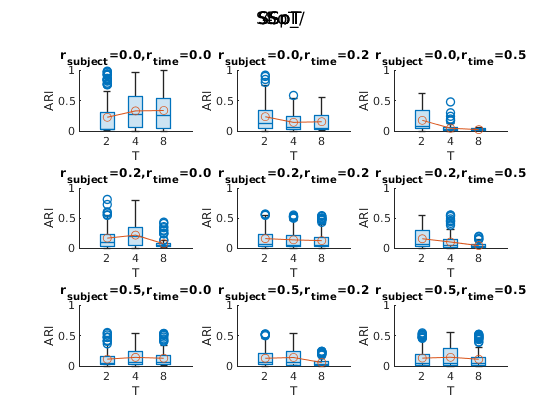

rs_name = ["r_{subject}=0.0", "r_{subject}=0.2", "r_{subject}=0.5"];
rt_name = ["r_{time}=0.0", "r_{time}=0.2", "r_{time}=0.5"];

figure
% sgtitle(main_dir(64:67))
sgtitle(main_dir(42:45))
for i = 1:3 % index for subject
    for j = 1:3 % index for time
        ij = 3*(i-1)+j;
        subplot(3,3,ij);
        [i1,i2,i3] = get_plot_index(i,j);

        if plot_option == "ori"
            ari = ari_ori_all(:,[i1,i2,i3]);
        elseif plot_option == "opt"
            ari = ari_opt_all(:,[i1,i2,i3]);
        end

        boxchart(ari);         
        hold on
        plot(mean(ari,1),'-o');
        
%         if plot_option == "oo"
%             boxchart(ari);
%             plot(mean(ari,1),'-o');
%             legend(["Tuned", "","General",""]);
%         end

        title(rs_name(i)+","+rt_name(j));
        xlabel("T");
        ylabel("ARI");
        ylim([0,1]);
        xticklabels([2,4,8]);

    end
end

[a,b,c]=get_plot_index(3,1)

a = 3

b = 6

c = 9

function [i1, i2, i3] = get_plot_index(i,j)
    % i : index for r_subject, range from 1,2,3
    % j : index for r_time, range from 1,2,3
    i1 = 9*(j-1)+(i-1)+1;
    i2 = 9*(j-1)+(i-1)+4;
    i3 = 9*(j-1)+(i-1)+7;
end

function [ari_mean, ari_med, ari_max] = summary_rep(rep_dir, width)
    global n_sample;

    K_edges = 0:width:240;
    ari_i = load([rep_dir,'/aris_ori.mat']).aris;
    z = load([rep_dir,'/z_ori.mat']).zS;
    size_z = size(z);
    K_ori = zeros([size_z(1), size_z(2), size_z(4)]);

    % find the number of communities (K) for each s,t, and sample
    for s = 1:size_z(1)
        for t = 1:size_z(2)
            for sample = 1:size_z(4)
                K_ori(s,t,sample) = max(unique(z(s,t,:,sample)));
            end
        end
    end
    
    % Average among subjects and time
    K_st = mean(K_ori, [1,2]);  % K_st: mean of K among subjects and time
    K_st = reshape(K_st, n_sample, 1);
    [counts,~] = histcounts(K_st, K_edges);
    [~, i_freq] = max(counts);
    K_mask = K_st>= K_edges(i_freq) & K_st<K_edges(i_freq+1);
    
    ari = mean(ari_i,[1,2]);
    ari = reshape(ari, n_sample, 1);
    ari_freq = ari(K_mask);    

    ari_max = max(ari_freq);
    ari_mean = mean(ari_freq); 
    ari_med = median(ari_freq);
end